# A simple demonstration of an ROC

This requres CANlab Core tools, and uses the CANlab function **roc_plot**

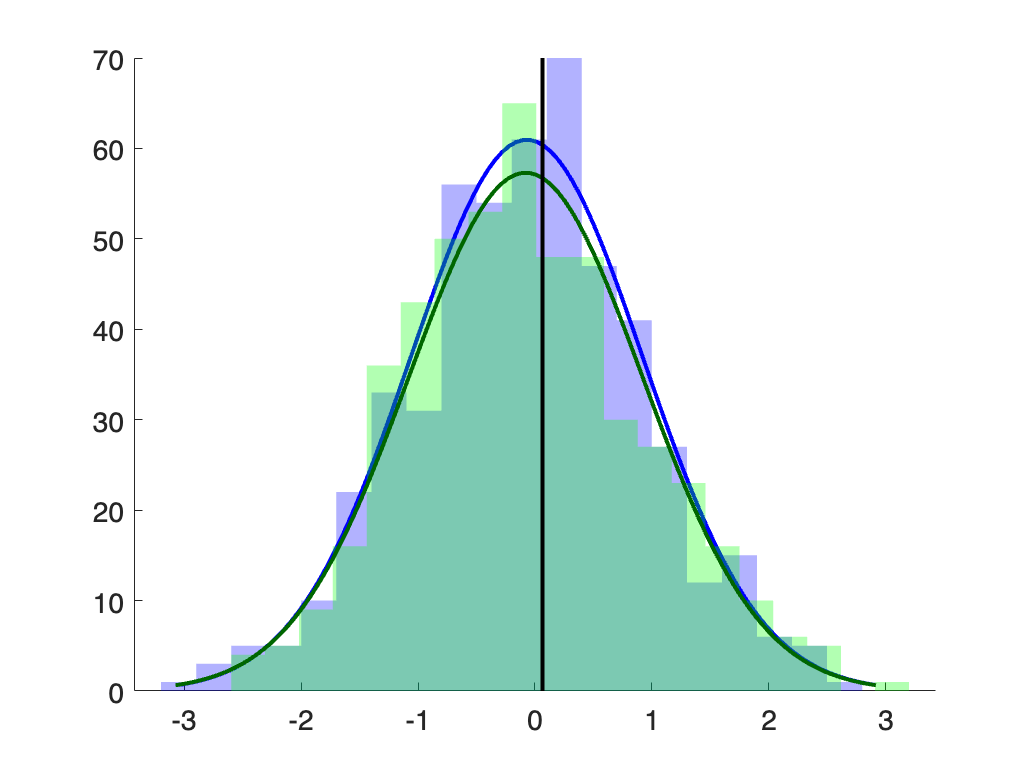


ROC_PLOT Output: Single-interval, Optimal overall accuracy
Threshold:	0.06	Sens:	 46% CI(42%-50%)	Spec:	 59% CI(55%-64%)	PPV:	NaN% CI(NaN%-NaN%)	Threshold:	50.50	Sens:	NaN% CI(50%-NaN%)	Spec:	NaN% CI(NaN%-NaN%)	PPV:	 50% CI(NaN%-50%)	Threshold:	NaN	Sens:	NaN% CI(NaN%-50%)	Spec:	 50% CI(50%-50%)	PPV:	NaN% CI(NaN%-50%)	Threshold:	50.50	Sens:	NaN% CI(NaN%-NaN%)	Spec:	NaN% CI(NaN%-50%)	PPV:	 50% CI(NaN%-NaN%)	Threshold:	50.50	Sens:	NaN% CI(NaN%-NaN%)	Spec:	 50% CI(50%-50%)	PPV:	 50% CI(NaN%-NaN%)	Threshold:	NaN	Sens:	NaN% CI(50%-NaN%)	Spec:	 50% CI(50%-50%)	PPV:	 50% CI(NaN%-50%)	Threshold:	NaN	Sens:	NaN% CI(NaN%-NaN%)	Spec:	 50% CI(50%-NaN%)	PPV:	NaN% CI(NaN%-50%)	Threshold:	NaN	Sens:	NaN% CI(50%-NaN%)	Spec:	NaN% CI(NaN%-50%)	PPV:	NaN% CI(NaN%-NaN%)	Threshold:	50.50	Sens:	NaN% CI(NaN%-NaN%)	Spec:	NaN% CI(50%-50%)	PPV:	NaN% CI(NaN%-NaN%)	Threshold:	NaN	Sens:	 50% CI(NaN%-50%)	Spec:	NaN% CI(50%-NaN%)	PPV:	NaN% CI(NaN%-50%)	Threshold:	50.50	Sens:	 50% CI(NaN%-50%)	Spec:	 50% CI(50%-50%)	PPV

% Create 1000 cases where a true effect is either present or absent
true_effect = unifrnd(0, 1, 1000, 1) > 0.5;

% Simulate hypothetical beta-hat 
% t-values are identical in both cases; the test statistic is not informative 
betahat(true_effect == 0) = randn(sum(true_effect == 0), 1);
betahat(true_effect == 1) = randn(sum(true_effect == 1), 1);

create_figure('ROC_badmodel');
ROC = roc_plot(betahat, true_effect, 'color', 'k', 'plothistograms');

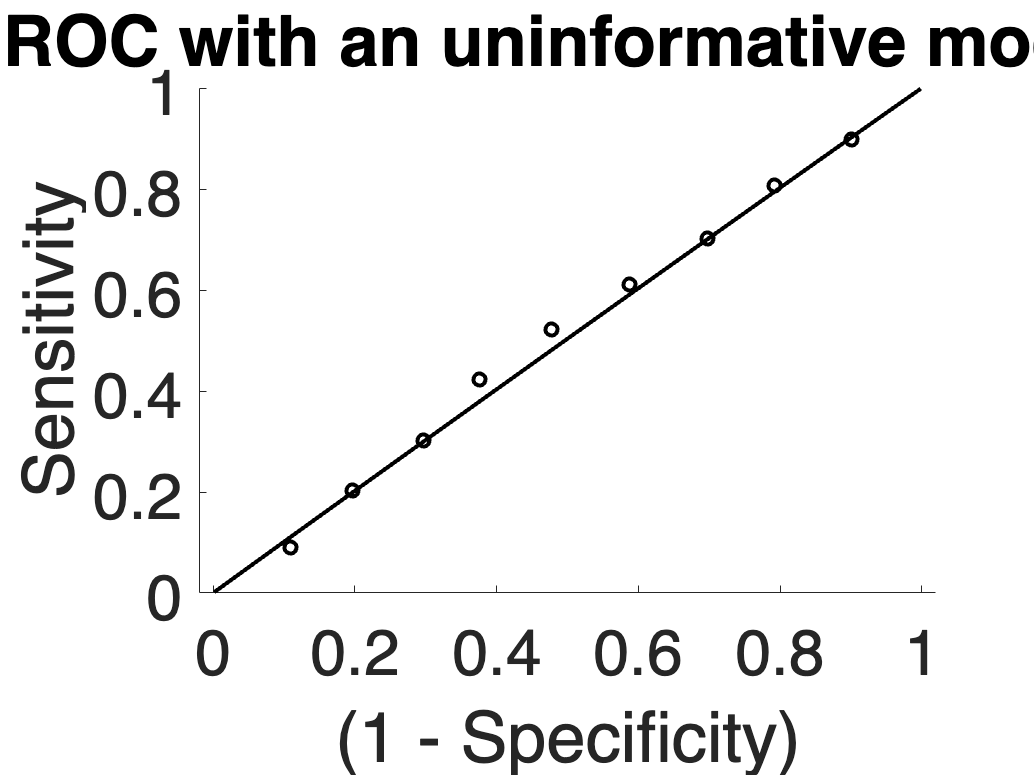


title('ROC with an uninformative model')

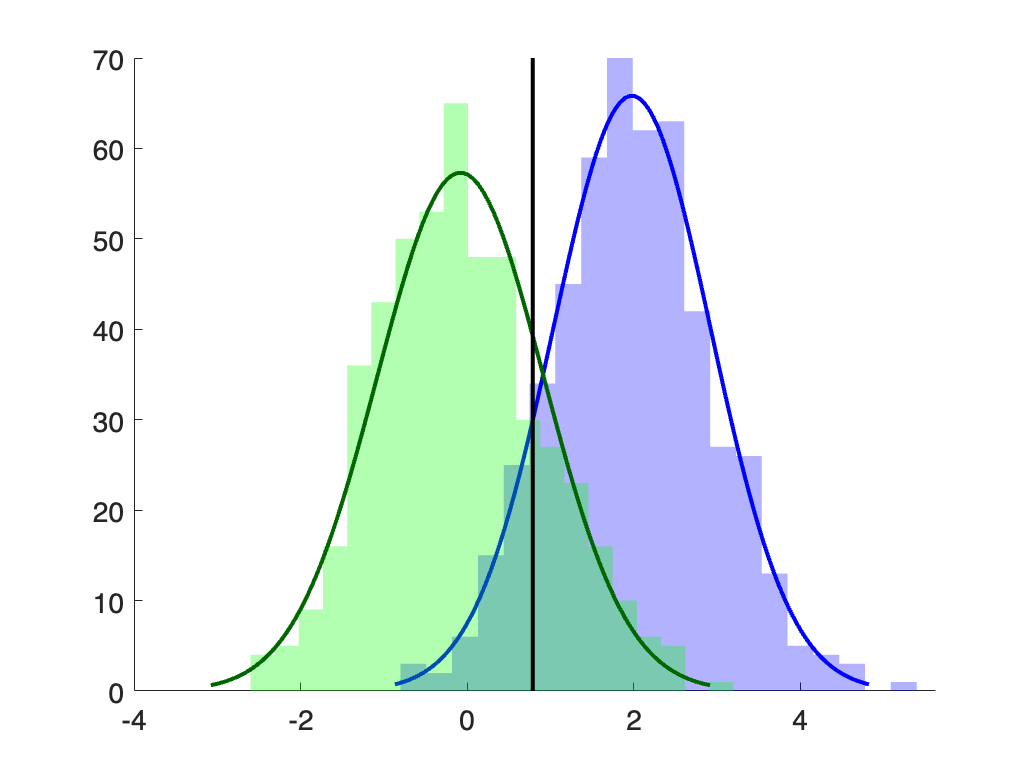


ROC_PLOT Output: Single-interval, Optimal overall accuracy
Threshold:	0.79	Sens:	 90% CI(87%-93%)	Spec:	 81% CI(77%-84%)	PPV:	NaN% CI(NaN%-NaN%)	Threshold:	50.50	Sens:	NaN% CI(NaN%-50%)	Spec:	NaN% CI(NaN%-50%)	PPV:	 50% CI(NaN%-50%)	Threshold:	NaN	Sens:	NaN% CI(NaN%-NaN%)	Spec:	 50% CI(50%-50%)	PPV:	NaN% CI(NaN%-50%)	Threshold:	50.50	Sens:	NaN% CI(NaN%-50%)	Spec:	NaN% CI(NaN%-NaN%)	PPV:	NaN% CI(50%-NaN%)	Threshold:	NaN	Sens:	 50% CI(50%-NaN%)	Spec:	 50% CI(50%-50%)	PPV:	 50% CI(NaN%-50%)	Threshold:	50.50	Sens:	 50% CI(NaN%-50%)	Spec:	NaN% CI(50%-NaN%)	PPV:	NaN% CI(NaN%-NaN%)	Threshold:	NaN	Sens:	 50% CI(50%-50%)	Spec:	 50% CI(NaN%-NaN%)	PPV:	 50% CI(NaN%-NaN%)	Threshold:	NaN	Sens:	 50% CI(NaN%-50%)	Spec:	NaN% CI(NaN%-50%)	PPV:	 50% CI(NaN%-NaN%)	Threshold:	NaN	Sens:	 50% CI(50%-NaN%)	Spec:	NaN% CI(50%-50%)	PPV:	NaN% CI(NaN%-NaN%)	Threshold:	NaN	Sens:	NaN% CI(NaN%-50%)	Spec:	NaN% CI(50%-NaN%)	PPV:	NaN% CI(NaN%-50%)	Threshold:	50.50	Sens:	 50% CI(50%-NaN%)	Spec:	 50% CI(50%-NaN%)	PPV:	N

create_figure('ROC_goodmodel');
% Now repeat, but with a true effect size of 2
betahat(true_effect == 1) = 2 + randn(sum(true_effect == 1), 1);

ROC = roc_plot(betahat, true_effect, 'color', 'r', 'plothistograms');

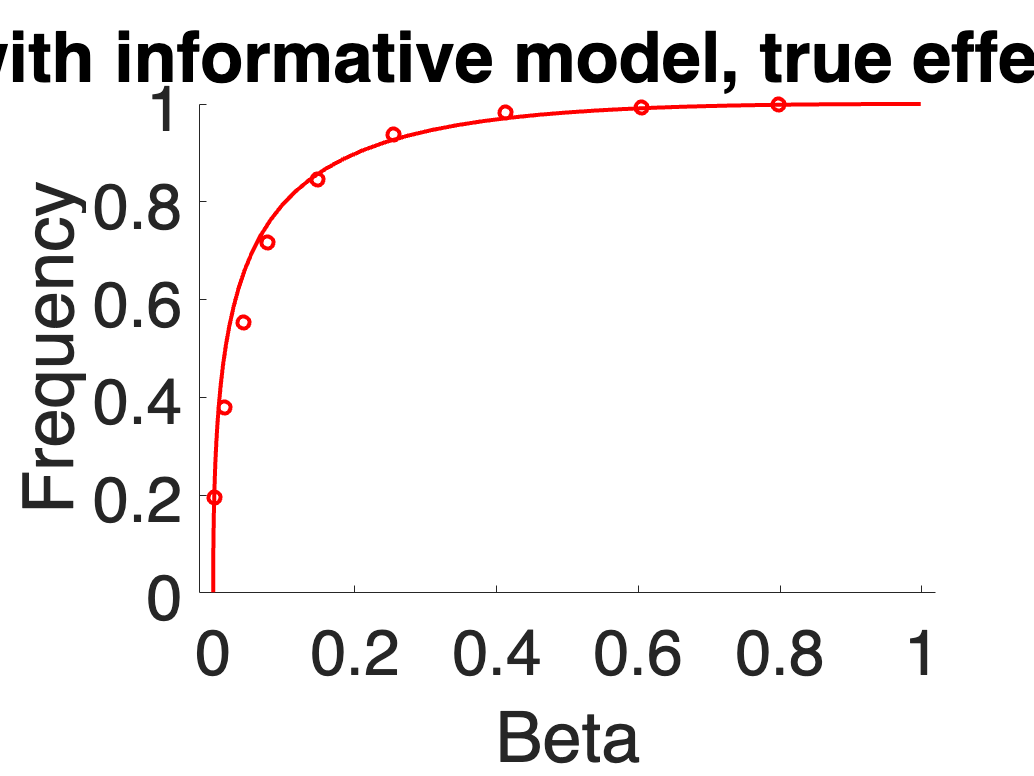

xlabel('Beta');
ylabel('Frequency');
title('Null distribution in green, alternative in blue')

figure(findobj('Tag', 'ROC_goodmodel'))
title('Informative model, true effect = 2 SE')